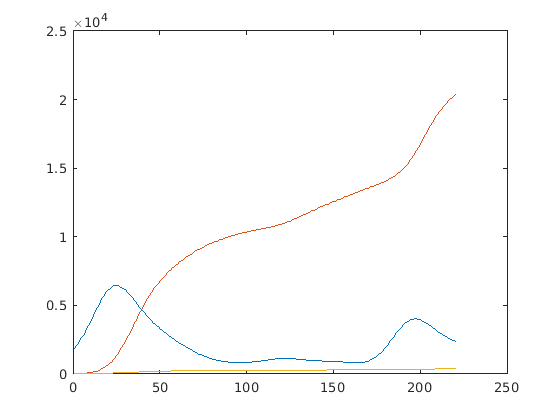

load('../Data/Korea.mat')
ydata = [Cases-Recovered-Death;Recovered; Death];

time = 30:250;
ydata = [ydata(1,time); ydata(2,time); ydata(3,time)];
ydata = smoothdata(ydata,2,'gaussian');
CasesAct = Cases(1,time);
figure
plot(ydata')

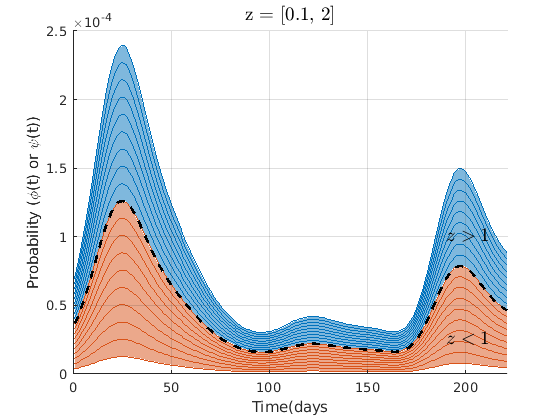

aleph = @(S,I,nu) 1 + nu*I./(I+S);

phi = @(S,I,N,z,nu) 1-(1-1./(S+1)).^(z*I.*(S/N).^aleph(S,I,nu*8e4));
psi = @(S,I,N,z,nu) 1-(1-(I/N).^aleph(S,I,nu)).^z;
clas = @(S,I,N,z,nu) z*(I/N).^aleph(S,I,nu);


N = 5.1e7;
S = N-sum(ydata,1);
I = ydata(1,:);
R = sum(ydata(2:end,:),1);

xdata = 1:length(I);

A = rand(6,3);
cm = colormap(lines(size(A,1)));

z_1 = 0.1:0.1:1;
z_2 = 1:0.1:2;
% z2 = 1;
nu = 0;

% ale = zeros(length(z_1),length(I));
prob1 = zeros(length(z_1),length(I));
prob2 = zeros(length(z_1),length(I));

prob1_2 = zeros(length(z_1),length(I));
prob2_2 = zeros(length(z_1),length(I));

% prob3 = clas(S,I,N,z2,nu);
ref = clas(S,I,N,1,0);

for i = 1:length(z_1)
%     ale(i,:) = aleph(S,I,nu);
    prob1(i,:) = phi(S,I,N,z_1(i),nu);
    prob2(i,:) = psi(S,I,N,z_1(i),nu);
    
    prob1_2(i,:) = phi(S,I,N,z_2(i),nu);
    prob2_2(i,:) = psi(S,I,N,z_2(i),nu);
end

close all
figure(1)
% subplot(1,2,1)
hold on
area(xdata,max(prob2_2),'facecolor', cm(1,:),'FaceAlpha',0.5,'EdgeColor','w')
area(xdata,min(prob2_2),'facecolor','w','EdgeColor','w')
plot(xdata,prob2_2,'color',cm(1,:))

area(xdata,max(prob2),'facecolor', cm(2,:),'FaceAlpha',0.5,'EdgeColor','w')
area(xdata,min(prob2),'facecolor','w','EdgeColor','w')
plot(xdata,prob2,'color',cm(2,:))
plot(xdata,ref,'--k','LineWidth',2)


text(190,1e-4, "$z>1$",'FontSize',14,'FontWeight',"bold",'Interpreter',"latex")
text(190,0.25e-4, "$z<1$",'FontSize',14,'FontWeight',"bold",'Interpreter',"latex")

grid on

xlim([0 xdata(end)])
xlabel('Time(days')
ylabel('Probability (\phi(t) or \psi(t))')
Ax = gca;
Ax.YGrid = 'on';
Ax.Layer = 'top';
title("z = " + '['+ num2str(min(z_1)) + ', ' + num2str(max(z_2)) +']','Interpreter',"latex",'FontSize',14)
FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/";
savefig(FolderFigures + "Sim_Prob_z.fig")
saveas(gcf, FolderFigures + "Sim_Prob_z.png")


% subplot(1,2,2)
% hold on
% area(xdata,max(prob1_2),'facecolor', cm(1,:),'FaceAlpha',0.5,'EdgeColor','w')
% area(xdata,min(prob1_2),'facecolor','w','EdgeColor','w')
% 
% area(xdata,max(prob1),'facecolor', cm(2,:),'FaceAlpha',0.5,'EdgeColor','w')
% area(xdata,min(prob1),'facecolor','w','EdgeColor','w')
% plot(xdata,ref,'--k','LineWidth',2)
% grid on
% 
% xlim([0 xdata(end)])
% xlabel('Time(days')
% ylabel('\phi(t)')
% suptitle("z = " + '['+ num2str(min(z_1)) + ', ' + num2str(max(z_2)) +']')
% Ax = gca;
% Ax.YGrid = 'on';
% Ax.Layer = 'top';

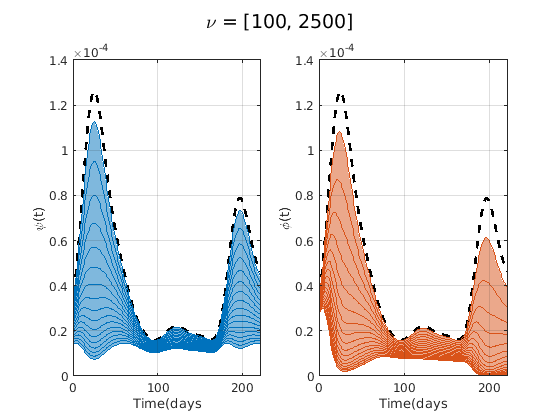

z = 1;
z2 = 1;
nu = 100:150:2500;

ale = zeros(length(nu),length(I));
prob1 = zeros(length(nu),length(I));
prob2 = zeros(length(nu),length(I));

% prob3 = clas(S,I,N,z2,nu);
ref = clas(S,I,N,1,0);

for i = 1:length(nu)
    ale(i,:) = aleph(S,I,nu(i));
    prob1(i,:) = phi(S,I,N,z,nu(i));
    prob2(i,:) = psi(S,I,N,z,nu(i));
end

close all
figure(1)
subplot(1,2,1)
area(xdata,max(prob2),'facecolor', cm(1,:),'FaceAlpha',0.5,'EdgeColor' ,'w')
hold on
area(xdata,min(prob2),'facecolor','w','EdgeColor','w')
plot(xdata,ref,'--k','LineWidth',2)
plot(xdata,prob2,'color', cm(1,:)')
grid on

xlim([0 xdata(end)])
xlabel('Time(days')
ylabel('\psi(t)')
Ax = gca;
Ax.YGrid = 'on';
Ax.Layer = 'top';

subplot(1,2,2)
area(xdata,max(prob1),'facecolor', cm(2,:),'FaceAlpha',0.5,'EdgeColor','w')
hold on
area(xdata,min(prob1),'facecolor','w','EdgeColor','w')
plot(xdata,ref,'--k','LineWidth',2)
plot(xdata,prob1,'color', cm(2,:)')

grid on

xlim([0 xdata(end)])
xlabel('Time(days')
ylabel('\phi(t)')
suptitle("\nu = " + '['+ num2str(min(nu)) + ', ' + num2str(max(nu)) +']')
Ax = gca;
Ax.YGrid = 'on';
Ax.Layer = 'top';
savefig(FolderFigures + "Sim_Prob_nu.fig")
saveas(gcf, FolderFigures + "Sim_Prob_nu.png")

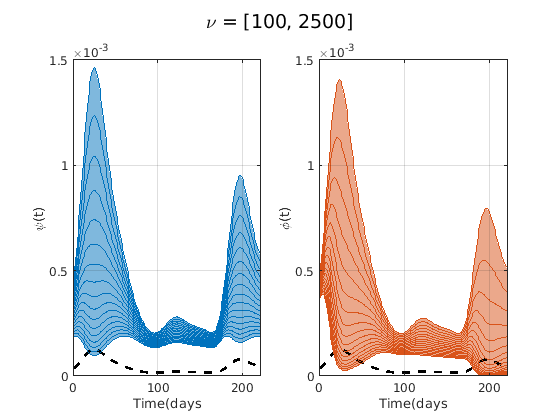

z = 13;
z2 = 1;
nu = 100:150:2500;

ale = zeros(length(nu),length(I));
prob1 = zeros(length(nu),length(I));
prob2 = zeros(length(nu),length(I));

% prob3 = clas(S,I,N,z2,nu);
ref = clas(S,I,N,1,0);

for i = 1:length(nu)
    ale(i,:) = aleph(S,I,nu(i));
    prob1(i,:) = phi(S,I,N,z,nu(i));
    prob2(i,:) = psi(S,I,N,z,nu(i));
end

close all
figure(3)
subplot(1,2,1)
area(xdata,max(prob2),'facecolor', cm(1,:),'FaceAlpha',0.5,'EdgeColor','w')
hold on
area(xdata,min(prob2),'facecolor','w','EdgeColor','w')
plot(xdata,ref,'--k','LineWidth',2)
plot(xdata,prob2,'color', cm(1,:)')
grid on

xlim([0 xdata(end)])
xlabel('Time(days')
ylabel('\psi(t)')
Ax = gca;
Ax.YGrid = 'on';
Ax.Layer = 'top';

subplot(1,2,2)
area(xdata,max(prob1),'facecolor', cm(2,:),'FaceAlpha',0.5,'EdgeColor','w')
hold on
area(xdata,min(prob1),'facecolor','w','EdgeColor','w')
plot(xdata,ref,'--k','LineWidth',2)
plot(xdata,prob1,'color', cm(2,:)')
grid on

xlim([0 xdata(end)])
xlabel('Time(days')
ylabel('\phi(t)')
suptitle("\nu = " + '['+ num2str(min(nu)) + ', ' + num2str(max(nu)) +']')
Ax = gca;
Ax.YGrid = 'on';
Ax.Layer = 'top';
savefig(FolderFigures + "Sim_Prob_nu_z.fig")
saveas(gcf, FolderFigures + "Sim_Prob_nu_z.png")